clear all
syms x1 x2 x3 x4 u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
Ts=0.1;% tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)  <- ESTADO NO LINEAL
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);

% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;

% Jacobiano simbólico
As=[diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4);...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4);...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4);...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)];

Bs=[diff(f1,u);diff(f2,u);diff(f3,u);diff(f4,u)];

C=[1 0 0 0];
D=[0];

% Ampliar A y B para acción integral
Aa = [As, zeros(4,1); -C, 0];
Bb = [Bs; 0];

%% Parámetros del controlador
zeta = 0.8;
tsdes = 2;
wn = 4.6 / (zeta * tsdes);
sistReferencia = tf([0 0 1],[1 2*zeta*wn wn^2]);
polosz = [pole(sistReferencia)' -1 -6 -5];

%% GAIN SCHEDULING BASADO EN EL ÁNGULO DEL PÉNDULO (x3 = theta)
% Cambiamos phi_vector por theta_vector
theta_vector = deg2rad(-70:1:70);  % Rango amplio del ángulo del péndulo
Ka = zeros(length(theta_vector), 5);  % matriz de ganancias

% Punto de operación actual
x1op = 0.1;
x2op = 0;
x3op = 0.1;
x4op = 0;

% Estimar uop (opcional, si es necesario)
uop = (3*g*la*mp*sin(2*x3op))/8;  % o simplemente usar el último `u`

% Evaluar Jacobianos
A_sym = jacobian([f1; f2; f3; f4], [x1, x2, x3, x4]);
B_sym = jacobian([f1; f2; f3; f4], u);

A_num = double(subs(A_sym, [x1, x2, x3, x4, u], [x1op, x2op, x3op, x4op, uop]));
B_num = double(subs(B_sym, [x1, x2, x3, x4, u], [x1op, x2op, x3op, x4op, uop]));

% Crear sistema discreto
SistCont = ss(A_num, B_num, eye(4), zeros(4,1));
SysDisc = c2d(SistCont, Ts);

% % Actualizar el modelo del MPC
MPCobj.Model.Nominal.Y = [x1op, x2op, x3op, x4op];
MPCobj.Model.Nominal.U = uop;
MPCobj = mpc(SysDisc, Ts);

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 y3 y4 


MPCobj.PredictionHorizon = 7;
MPCobj.ControlHorizon = 5;
MPCobj.MV.Min = -1;   % torque mínimo
MPCobj.MV.Max = 1;    % torque máximo
MPCobj.MV.RateMin = -0.4;
MPCobj.MV.RateMax = 0.4;
MPCobj.W.ManipulatedVariables = 0.01;
MPCobj.W.ManipulatedVariablesRate = 0;
MPCobj.W.OutputVariables = 1*[1, 0.4, 1, 0.4];  % tunear según importancia
% Definir referencia (por ejemplo, r para ángulo del brazo)
ref = [0 0 0 0];  % Solo el primer estado es la referencia
Tsim = 70;                     % Duración simulación
Ns = round(Tsim / Ts);         % Número de pasos
time = 0:Ts:(Tsim - Ts);
x_sim = zeros(4, Ns);          % Estados
u_sim = zeros(1, Ns);          % Control
ref = zeros(1, Ns);            % Referencia
xstate = mpcstate(MPCobj);     % Estado del MPC

   Assuming no disturbance added to measured output #1.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->Assuming output disturbance added to measured output #4 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


x_current = [0.2; 0; 0; 0];     % Condición inicial
umpc = 0;
r = 0.1;
% Variables para actualizar modelo solo cuando cambia significativamente
theta_prev = x_current(3);     
threshold = deg2rad(1);        % umbral de cambio para actualizar

fprintf("Simulando...\n");

Simulando...


warning off
for k = 1:Ns
    t = (k-1)*Ts;
    [~, x_out] = ode45(@(t, x) complex_rot_pend(t, x, [], umpc), [0 Ts], x_current);
    x_current = x_out(end, :)';
    % REFERENCIA ESCALONADA (ángulo del brazo)
    if time(k) >= 0.1 && time(k-1) < 0.1
        r = 0.4;
    elseif time(k) >= 15 && time(k-1) < 15
        r = 0.2;
    elseif time(k) >= 30 && time(k-1) < 30
        r = -0.2;
    elseif time(k) >= 45 && time(k-1) < 45
        r = 0.1;
    end
    ref(k) = r;

    % LINEALIZACIÓN ADAPTATIVA si θ cambia mucho
    theta_now = x_current(3);
    if abs(theta_now - theta_prev) > threshold
        x1op = x_current(1);
        x2op = x_current(2);
        x3op = x_current(3);
        x4op = x_current(4);
        uop = umpc;

        % Evaluar A y B
        A_eval = double(subs(As, [x1 x2 x3 x4 u], [x1op x2op x3op x4op uop]));
        B_eval = double(subs(Bs, [x1 x2 x3 x4 u], [x1op x2op x3op x4op uop]));

        % Crear modelo discreto
        SysCont = ss(A_eval, B_eval, eye(4), zeros(4,1));
        SysDisc = c2d(SysCont, Ts);

        % % Actualizar MPC
        % MPCobj.Model.Nominal.Y = [x1op x2op x3op x4op];
        % MPCobj.Model.Nominal.U = uop;
        % MPCobj.Model.Plant = SysDisc;

        theta_prev = theta_now;
    end

    % % Control con MPC adaptativo
    umpc = mpcmoveAdaptive(MPCobj, xstate, SysDisc, [], x_current, [r 0 0 0]);
    
    % Simular planta no lineal (paso adelante)
    
    % umpc = mpcmove(MPCobj, xstate, x_current,[r 0 0 0]);
    % Guardar datos
    x_sim(:, k) = x_current;
    u_sim(k) = umpc;
end

## Gráficas Mejoradas

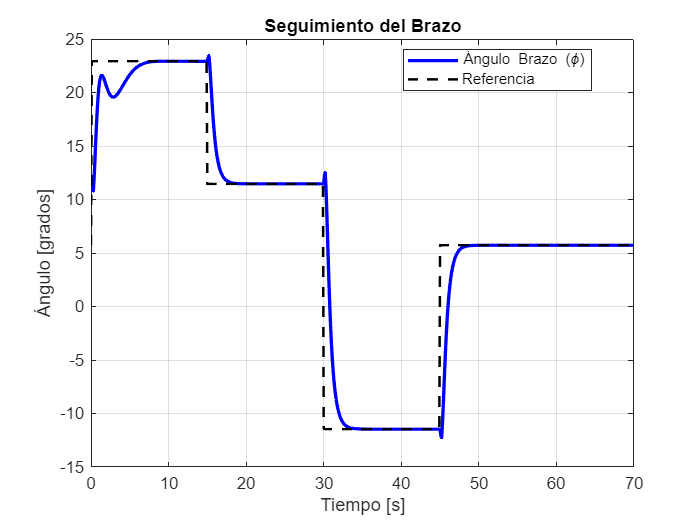



figure;
plot(time, x_sim(1,:)*180/pi, 'blue', 'LineWidth', 2)
hold on
plot(time, ref*180/pi, 'black--', 'LineWidth', 1.5);
ylabel('Ángulo [grados]')
xlabel('Tiempo [s]')
legend('Ángulo Brazo (\phi)', 'Referencia', 'Location', 'best');
title('Seguimiento del Brazo')
grid on

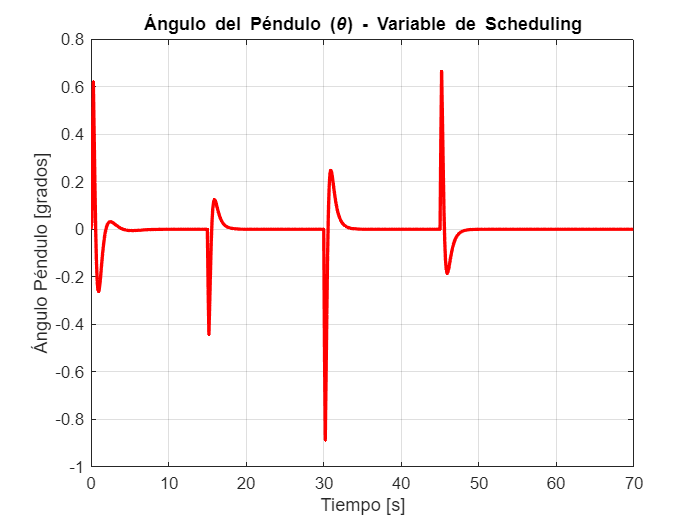

figure
plot(time, x_sim(3,:)*180/pi, 'red', 'LineWidth', 2)
ylabel('Ángulo Péndulo [grados]')
xlabel('Tiempo [s]')
title('Ángulo del Péndulo (\theta) - Variable de Scheduling')
grid on

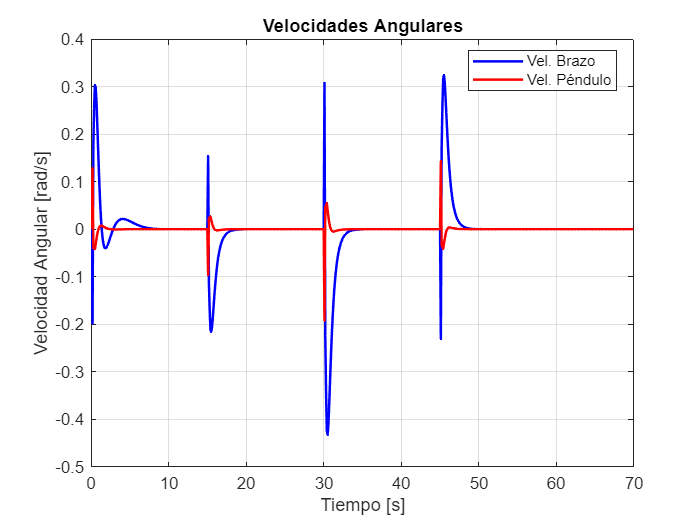


figure;
plot(time, x_sim(2,:), 'blue', 'LineWidth', 1.5)
hold on
plot(time, x_sim(4,:), 'red', 'LineWidth', 1.5)
ylabel('Velocidad Angular [rad/s]')
xlabel('Tiempo [s]')
legend('Vel. Brazo', 'Vel. Péndulo', 'Location', 'best');
title('Velocidades Angulares')
grid on

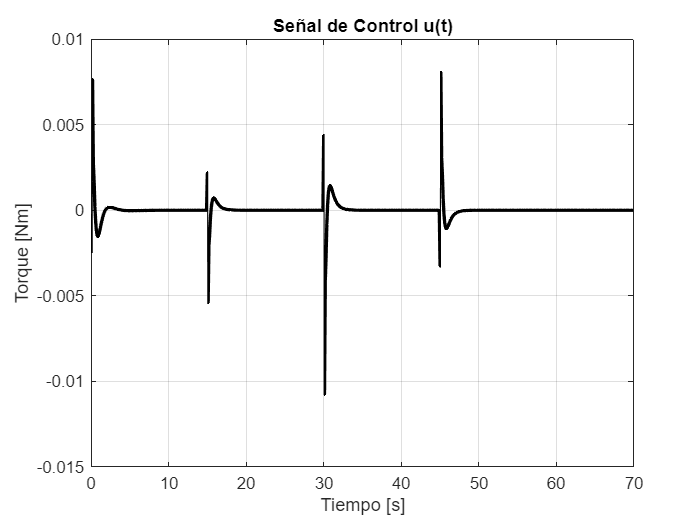

figure
plot(time, u_sim, 'k', 'LineWidth', 2)
ylabel('Torque [Nm]')
xlabel('Tiempo [s]')
title('Señal de Control u(t)')
grid on

fprintf("Simulación finalizada.\n");

Simulación finalizada.
